# **Script illustrating the relationship between cone spacing and point spread function in the default cone mosaic and optics models for the treeshrew and the human visual system**

*This script illustrates the relationship between cone spacing and the PSF in the treeshrew and in the human TreeShrew cone mosaics.*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1a.** Generate the default human and treeshrew optics

% Default treeshrew optics, here with 2.0 mm pupil
pupilDiameterMM = 2.0

pupilDiameterMM = 2

tOI = oiTreeShrewCreate('pupilDiameterMM', pupilDiameterMM);
% Default human optics, here with 2.0 mm pupil
hOI = oiCreate('wvf human', pupilDiameterMM);

# **Step 1b.** Generate human&treeshrew cone mosaics with L-cones only

#### Generate human and treeshrew L-cone only mosaics

% Specify an L-only mosaic (densities of other cones is 0)
spatialLMSdensities = [0 1 0 0];
% 0.5 x 0.5 deg mosaics
fovDegs = 0.1*[1 1];
% human mosaic
hMosaic = coneMosaicHex(7, ...
    'spatialDensity', spatialLMSdensities, ...
    'integrationTime', 5/1000, ...
    'fovDegs', fovDegs);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 0
Scones after making an S-cone free central patch: 0 (added Lcones:0, added Mcones:0)


% Treeshrew mosaic
fovDegs = 0.4*[1 1];
tMosaic = coneMosaicTreeShrewCreate(tOI.optics.micronsPerDegree, ...
    'spatialDensity', spatialLMSdensities, ...
    'integrationTime', 5/1000, ...
    'fovDegs', fovDegs);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 0
Scones after making an S-cone free central patch: 0 (added Lcones:0, added Mcones:0)


#### Visualize the mosaics

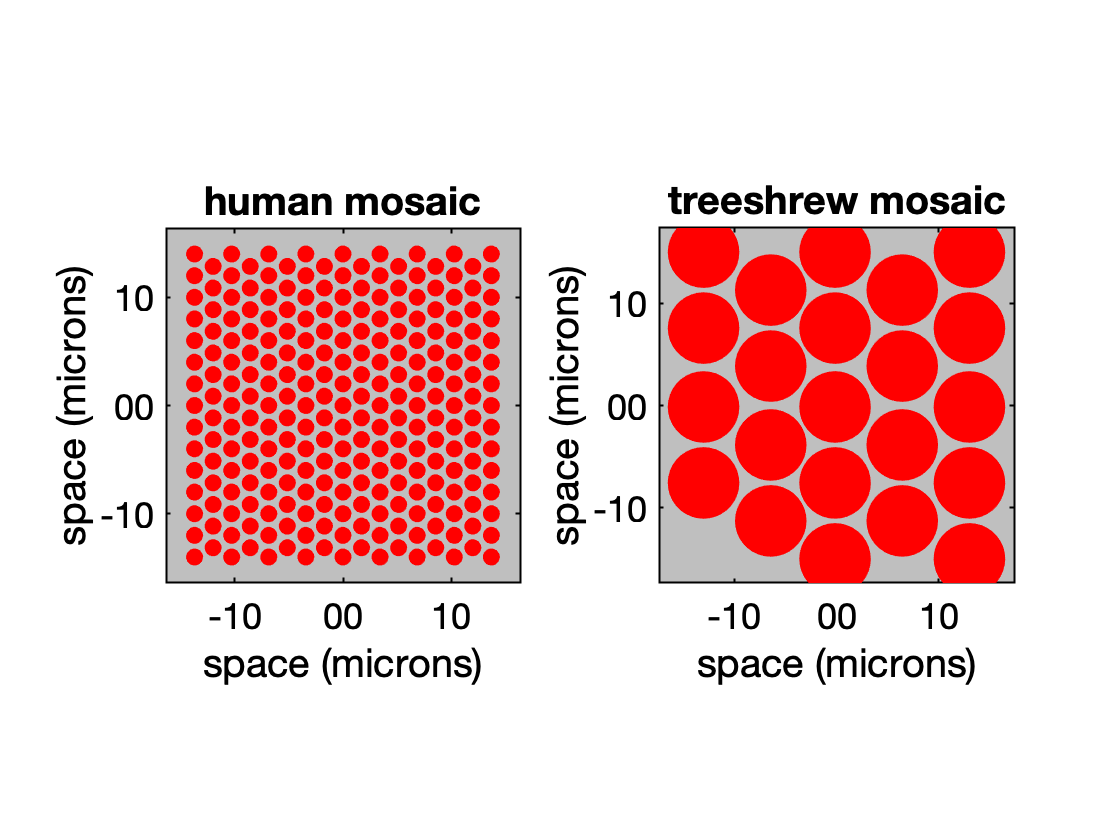

% Plot mosaics
figure(); clf;
subplot(1,2,1);
hMosaic.visualizeGrid('axesHandle', gca, 'ticksInMicrons', true);
title('human mosaic')

subplot(1,2,2);
tMosaic.visualizeGrid('axesHandle', gca, 'ticksInMicrons', true);
title('treeshrew mosaic')

# **Step 2.** Create a scene that emits equal photon rates at all wavelengths and compute the optical image for the human and treeshrew optics

% Create the equal photon rate test scene
testScene = sceneCreate('uniformEqualPhoton');
% Compute the retinal images
tOI = oiCompute(tOI, testScene);
hOI = oiCompute(hOI, testScene);

% Retrieve the retinal irradiances
meanIlluminanceTreeShrewRetina = oiGet(tOI, 'mean illuminance')

meanIlluminanceTreeShrewRetina = 14.3413

meanIlluminanceHumanRetina = oiGet(hOI, 'mean illuminance')

meanIlluminanceHumanRetina = 0.8480


% Compute ratio of mean illuminances
meanIlluminanceRatio = meanIlluminanceTreeShrewRetina/meanIlluminanceHumanRetina

meanIlluminanceRatio = 16.9127

Note that the ratio of mean illuminance in the treeshrew vs the human retina is around 17 times.

# **Step 3. **Compute treeshrew and human cone mosaic responses to the test scene

% Compute the mosaic responses
nTrialsNum = 3;
emPath = zeros(nTrialsNum, 1, 2);

% Compute *human* mosaic excitation responses to the *human* retinal image
hMosaicExcitation = hMosaic.compute(hOI, 'emPath', emPath);
% Compute *treeshrew* mosaic excitation responses to treeshrew optical image
tMosaicExcitation = tMosaic.compute(tOI, 'emPath', emPath);

% Find mean excitations
coneType = 2;
hMosaicExcitationMean = ...
    meanResponseToOpticalImage(hMosaic, hMosaicExcitation, coneType)

hMosaicExcitationMean = 17.4372

tMosaicExcitationMean = ...
    meanResponseToOpticalImage(tMosaic, tMosaicExcitation, coneType)

tMosaicExcitationMean = 658.8788


meanExcitationRatio = tMosaicExcitationMean / hMosaicExcitationMean

meanExcitationRatio = 37.7857

Here we see that the treeshrew mosaic excitation is 38-times higher than the human mosaic exciation. One factor contributing to this is the difference in retinal illuminances. But this can only account for around a 17-x factor. The remaining must be due to cone sensitivities. We examine this next.

w = cHuman.wave;
hPigment = cHuman.pigment

hPigment =   photoPigment with properties:

        opticalDensity: [3×1 double]
        peakEfficiency: [3×1 double]
                 width: 1.7725e-06
                height: 1.7725e-06
               pdWidth: 1.7725e-06
              pdHeight: 1.7725e-06
                  wave: [31×1 double]
            absorbance: [31×3 double]
           absorptance: [31×3 double]
    quantaFundamentals: [31×3 double]
    energyFundamentals: [31×3 double]
                  area: 3.1416e-12
                pdArea: 3.1416e-12
              gapWidth: 0
             gapHeight: 0



micronsPerDegree = 80

micronsPerDegree = 80

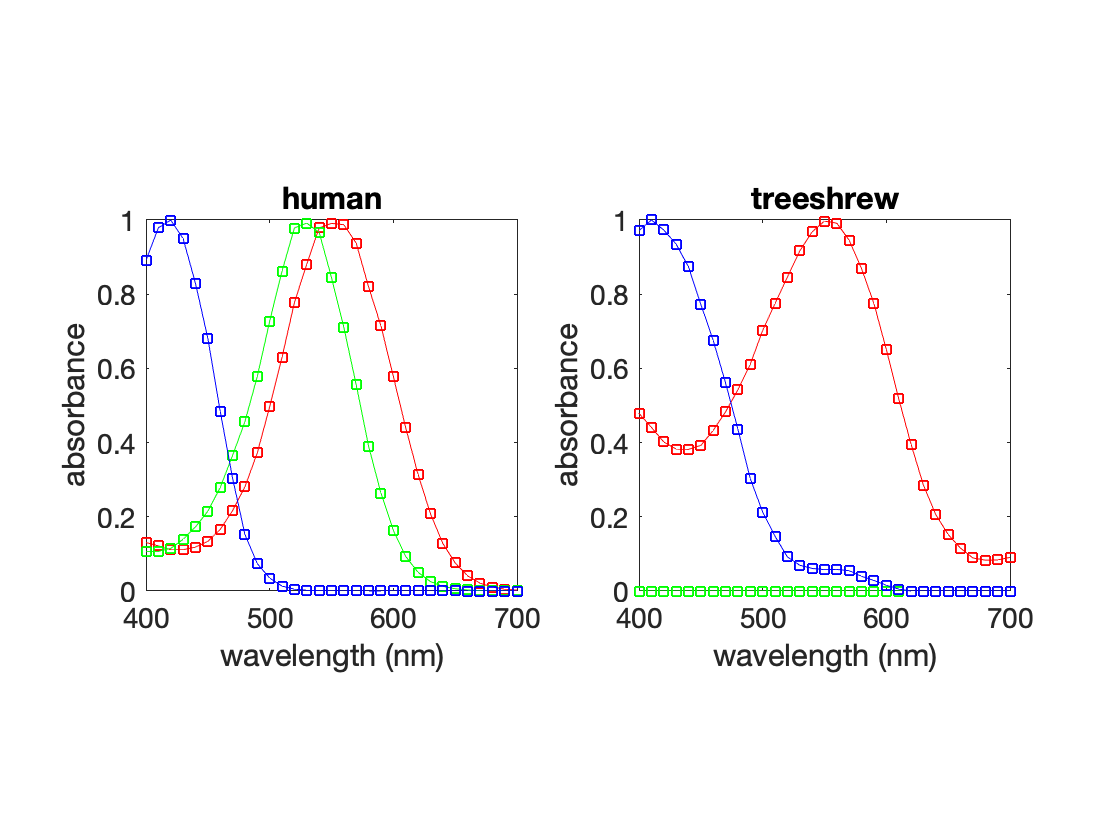

wT = cTreeShrew.wave;
tPigment = cTreeShrew.pigment;

% Retrieve the absorbance spectra. 
% Note that these are normalized to peak value of 1.
figure();
subplot(1,2,1)
humanAbsorbance = hPigment.absorbance;
plotActionSpectra(w, humanAbsorbance, 'absorbance', 'human')
subplot(1,2,2)
treeShrewAbsorbance = tPigment.absorbance;
plotActionSpectra(w, treeShrewAbsorbance, 'absorbance', 'treeshrew')

% Compute the axial absorbance, absorbance * axial optical density
axialDensities = hPigment.opticalDensity

axialDensities =     0.5000
    0.5000
    0.4000


humanAxialAbsorbance = humanAbsorbance * diag(axialDensities);
axialDensities = tPigment.opticalDensity

axialDensities =     0.0370
         0
    0.0389


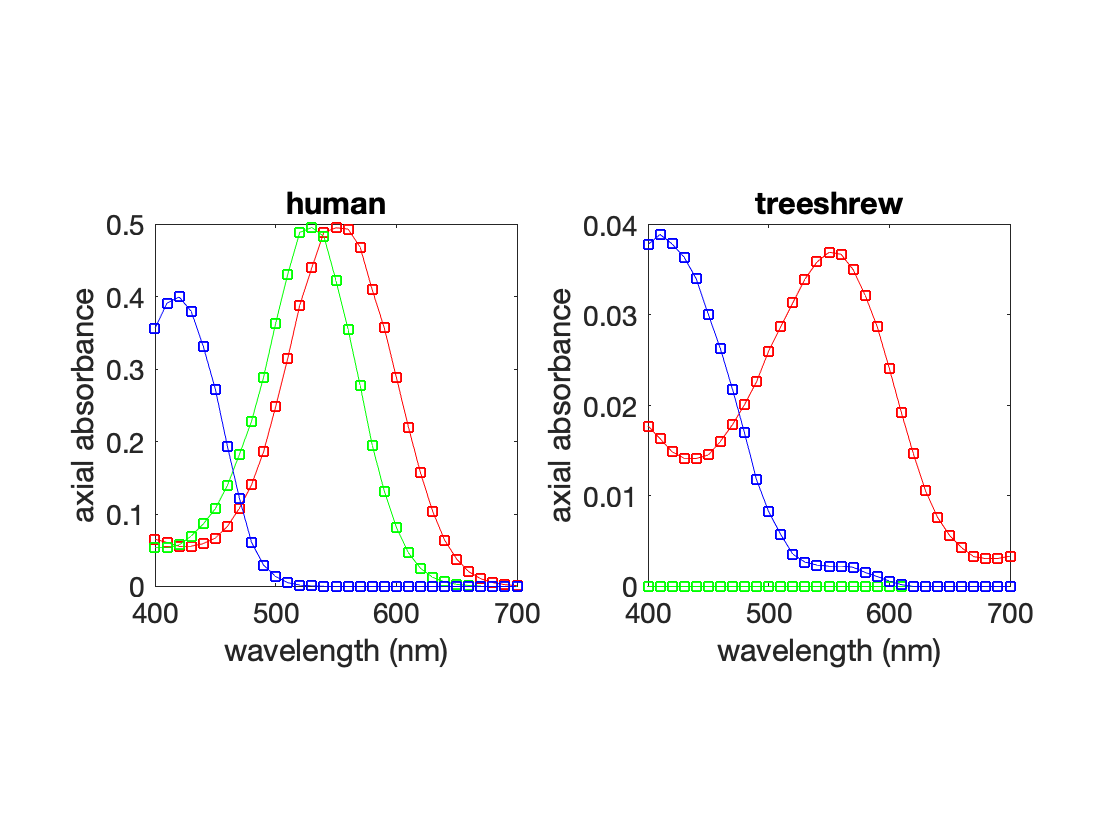

treeShrewAxialAbsorbance = treeShrewAbsorbance * diag(axialDensities);
figure()
subplot(1,2,1)
plotActionSpectra(w, humanAxialAbsorbance, 'axial absorbance', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewAxialAbsorbance, 'axial absorbance', 'treeshrew')

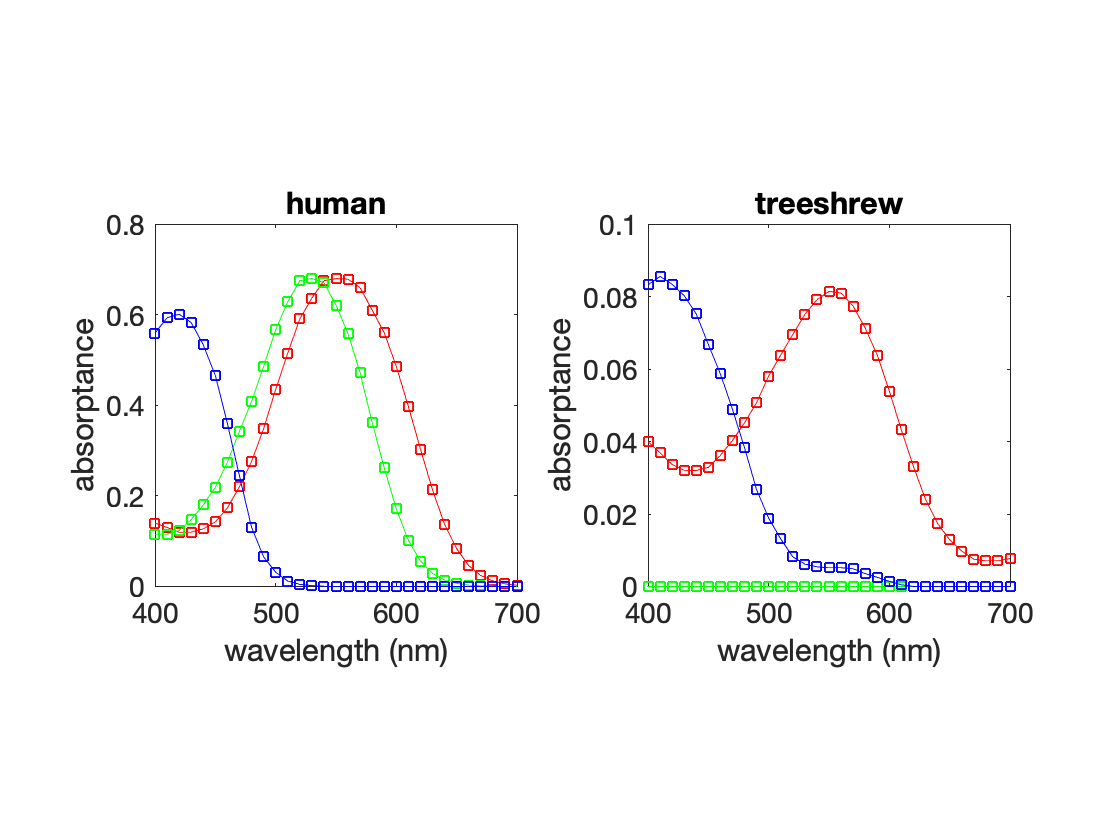


% Compute absorptance, the ratio of absorbed photons
humanAbsorptance = 1 - 10 .^ (-humanAxialAbsorbance);
treeShrewAbsorptance = 1 - 10 .^ (-treeShrewAxialAbsorbance);
figure()
subplot(1,2,1)
plotActionSpectra(w, humanAbsorptance, 'absorptance', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewAbsorptance, 'absorptance', 'treeshrew')

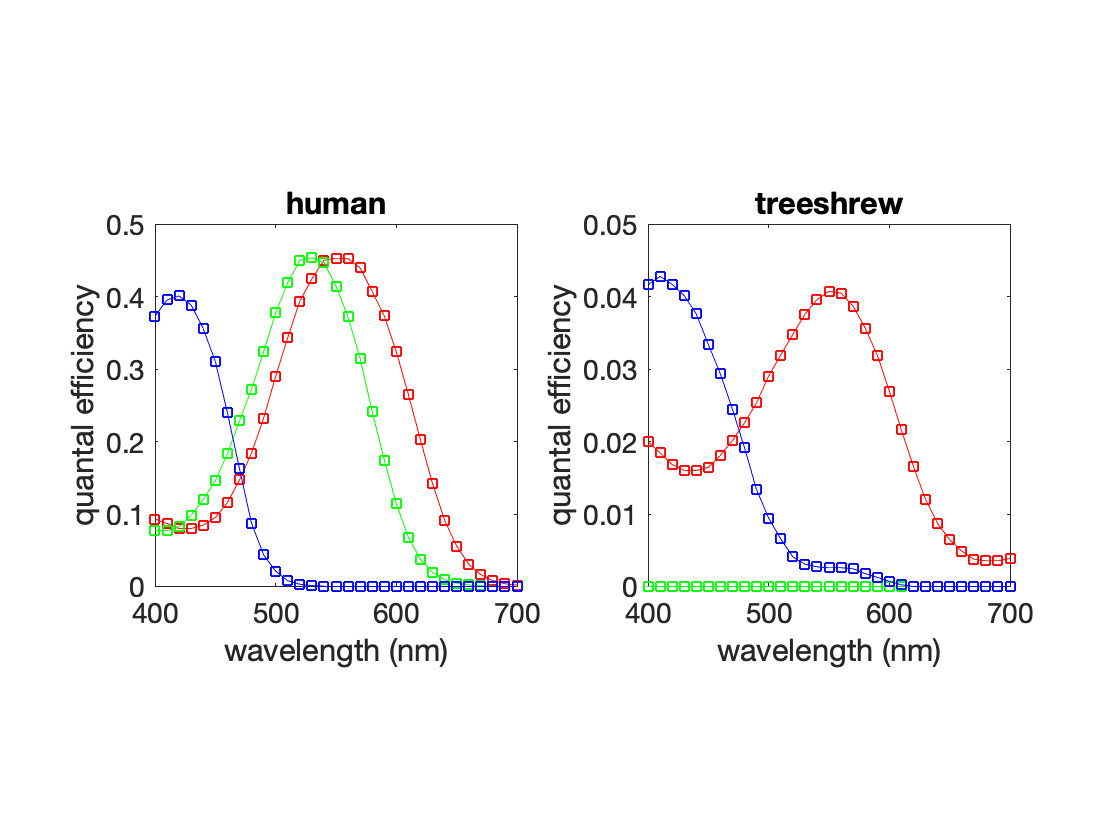

% Compute quantal efficiencies (not accounting for macular/lens pigments)
peakEfficiencies = hPigment.peakEfficiency;
humanQuantalEfficiency = humanAbsorptance * diag(peakEfficiencies);
peakEfficiencies = tPigment.peakEfficiency;
treeShrewQuantalEfficiency = treeShrewAbsorptance * diag(peakEfficiencies);
figure()
subplot(1,2,1)
plotActionSpectra(w, humanQuantalEfficiency, 'quantal efficiency', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewQuantalEfficiency, 'quantal efficiency', 'treeshrew')

% Compute integrated (over cone aperture) quantal efficiency 
innerSegmentArea = hPigment.pdArea*1e12

innerSegmentArea = 3.1416

humanIntegratedQuantalEfficiency = humanQuantalEfficiency * innerSegmentArea;
innerSegmentArea = tPigment.pdArea*1e12

innerSegmentArea = 28.2743

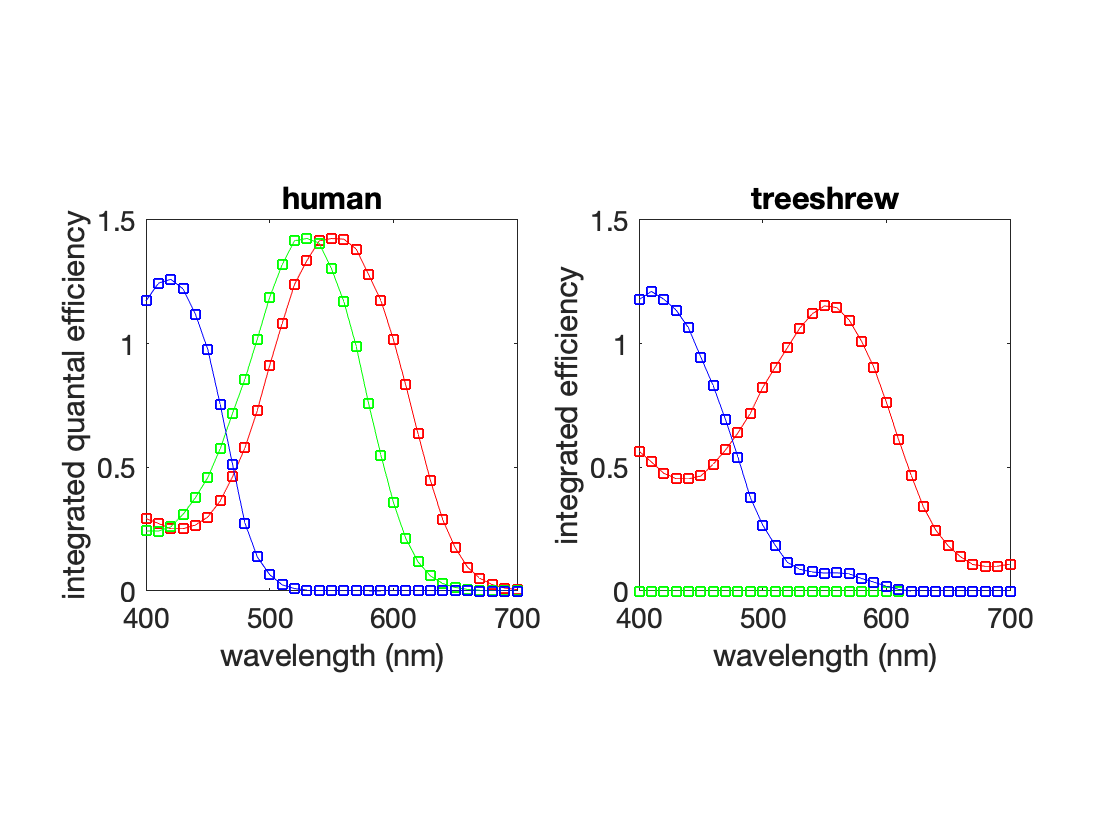

treeShrewIntegratedQuantalEfficiency = treeShrewQuantalEfficiency * innerSegmentArea;
figure()
subplot(1,2,1)
plotActionSpectra(w, humanIntegratedQuantalEfficiency, 'integrated quantal efficiency', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewIntegratedQuantalEfficiency, 'integrated efficiency', 'treeshrew')

function plotActionSpectra(w, a, aName, tName)
    plot(w, a(:,1), 'rs-'); hold on;
    plot(w, a(:,2), 'gs-');
    plot(w, a(:,3), 'bs-');
    axis 'square'
    xlabel('wavelength (nm)')
    ylabel(aName)
    title(tName)
    set(gca, 'FontSize', 14)
end



function meanResponse = meanResponseToOpticalImage(coneMosaic, coneMosaicResponse, targetConeType)
    nTrialsNum = size(coneMosaicResponse,1);
    coneMosaicResponse  = reshape(coneMosaicResponse, [nTrialsNum numel(coneMosaic.pattern)]);
    idx = find(coneMosaic.pattern == targetConeType);
    meanResponse = mean(mean(coneMosaicResponse(:,idx)));
end
